# Opdacht 7 - Matlab fourier

## Naam: Perijn Huijser

## Datum: 10-09-2025

## Opdracht

### Initialisatie

close all
clear

syms t

### A) Bepaal de periode tijd

T = 2 * sym(pi)

$$T = 2\,\pi$$

### B) Bepaal de hoeksnelheid

omega = 2 * sym(pi) / T

$$omega = 1$$

### C) Stel de functieomschrijving in

ft = @(a, b) piecewise((t > 0) & (t < a), 0, ...
                  (t > a) & (t < b), sin(sym(1/2)*t));

f_exp = ft(sym(1/3)*sym(pi),2 * sym(pi));

### D) Teken de bij c bepaalde functie

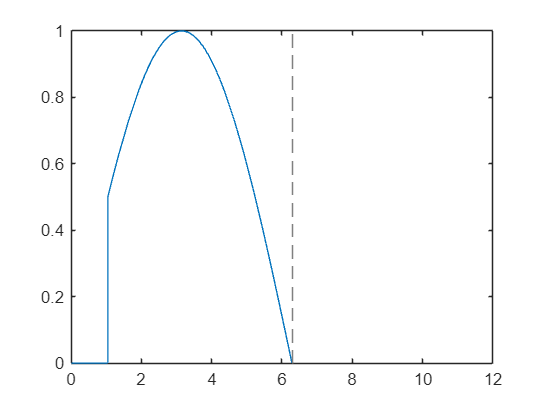

figure;
fplot(f_exp, [0,12])

### E) Is er sprake van symetrie

Nee er is geen sprake van symetrie

### F) wat zijn de consequenties van de gevonden symetrie

De an termen vervallen

### G & H) Bepaal de Fourier coefficienten

[anf, bnf, a0, an, bn] = FourierCoefficients(f_exp, t, T);

### I) Bepaal de eerst 7 Fourier coefficienten

An_list = an(1:7);
Bn_list = bn(1:7);

### J) Schrijf de eerste 7 termen van de Fourier reeks uit

terms = FourierSerie(f_exp, t, T, 7);

### K) Teken de Fourier reeks van de functie

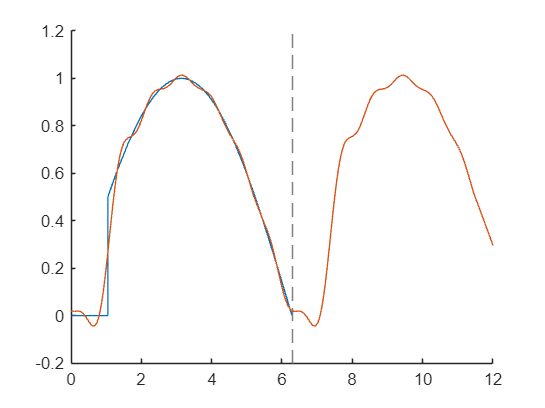

figure;
hold on;
fplot(f_exp, [0,12])
fplot(terms, [0,12])

### L) Vergelijk beide lijnen in de grafiek

De Fourierreeks periode lijkt best goed op de originele, behalve dat op het laagste moment er een raar stukje zit

### M) Bepaal THD voor respectievelijk 7 en 100 termen

syms k

Cn = @(n) sqrt(an(n)^2 + bn(n)^2);

% THD bij n = 7
Nominator = @(j) sqrt(symsum(Cn(k)^2, k, 2, j));

THD_7 = double(Nominator(7) / abs(Cn(1)))

THD_7 = 0.2973

THD_100 = double(Nominator(100) / abs(Cn(1)))

THD_100 = 0.3188

### N) Maak een lijnspectrum

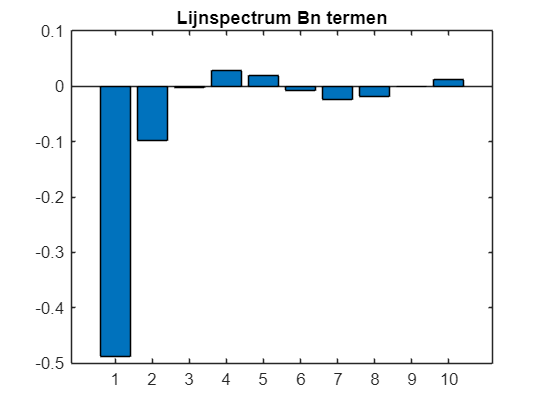

figure;
title("Lijnspectrum An termen")
bar(an(1:10))

title("Lijnspectrum Bn termen")

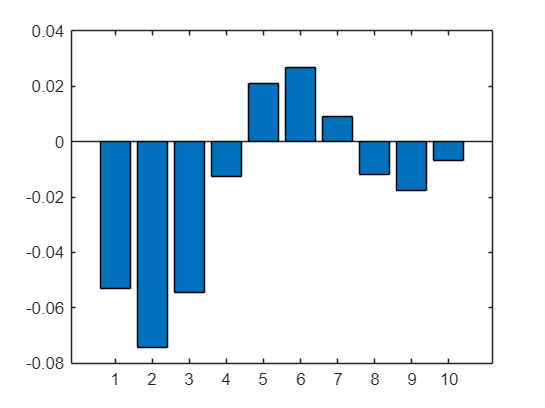

bar(bn(1:10))